# Ex6: Segmentation

E5ADSB, 39/2, Janus, Sep 2020

clc; close all; clear all;

## Part 1. Segmentation based on thresholding

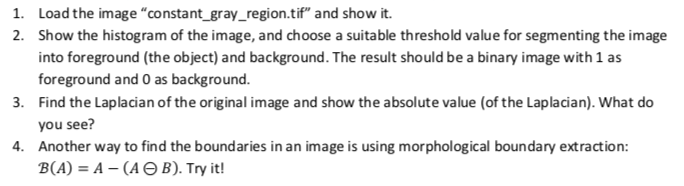

I = im2double(imread('img/constant_gray_region.tif'));

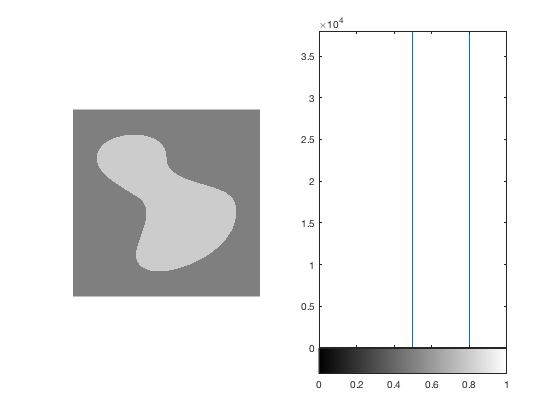

figure; 
subplot(121)
imshow(I);
subplot(122)
imhist(I);

The histogram shows a bimodal distribution. A manual choice for the threshold will be a value inbetween the two modes

T = 0.5*(0.8 + 0.5)        % Manual choice of threshold halfway inbetween modes

T = 0.6500

T_otsu = graythresh(I)      % Using Otsu 1979

T_otsu = 0.6471

The automatic choice of global threshold yields a value close to the manual.

Thresholding the image

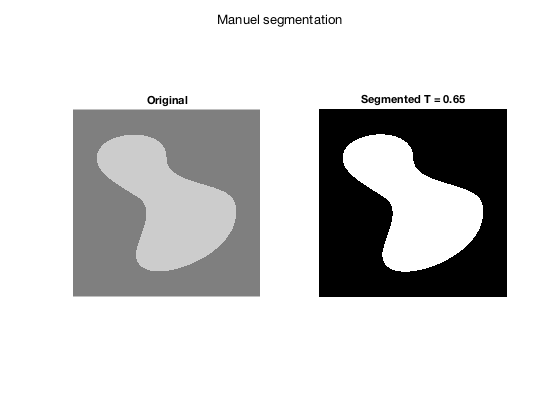

I_seg = I > T;              % Segmentation
figure; 
subplot(121)
imshow(I);
title('Original')
subplot(122)
imshow(I_seg);
title(['Segmented T = ', num2str(T)])
sgtitle('Manuel segmentation')

Segmentation using the Laplacian operator, $\nabla^2$.

g2 = [ 0 -1  0;
      -1  4 -1;
       0 -1  0];              % The 4-neighbour Laplacian, Marques p. 219
  

g2_8 = [-1 -1 -1;
        -1  8 -1;
        -1 -1 -1];              % The 8-neighbour Laplacian, Marques p. 219
  

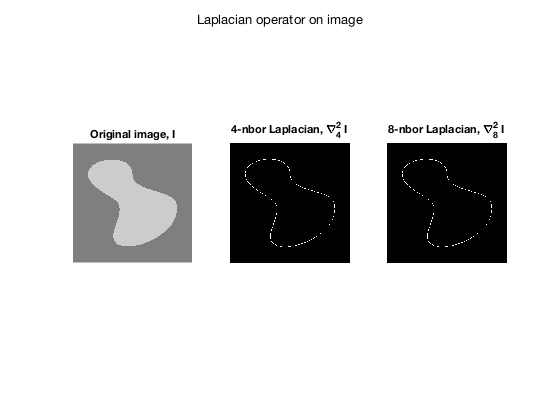

g2I = imfilter(I, g2, 'conv');      % filter with 4-nbor Laplacian
g2_8I = imfilter(I, g2_8, 'conv');  % filter with 8-nbor Laplacian

figure; 
subplot(131)
imshow(I);
title('Original image, I')

subplot(132)
imshow(imbinarize(abs(g2I)));               % Absolute value of Laplacian (avoid underflow)
title('4-nbor Laplacian, \nabla^2_4 I')

subplot(133)
imshow(imbinarize(abs(g2_8I)));               % Absolute value of Laplacian (avoid underflow)
title('8-nbor Laplacian, \nabla^2_8 I')

sgtitle('Laplacian operator on image')

The Laplacian detects edges and transitions. This could be a viable way to partition the image.

We can try to fatten the edge to get a fuller contour by dilating and binarizing again.

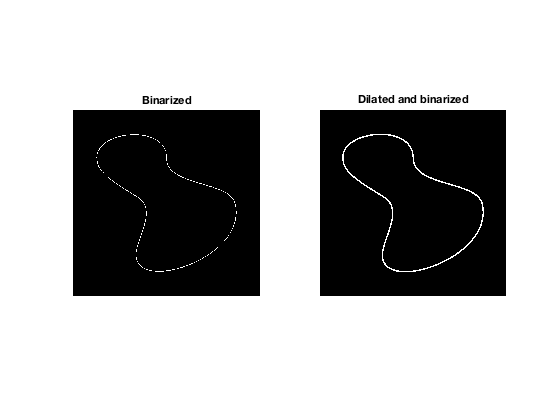

s = strel('square', 3);

Ib = imbinarize(abs(g2I));                      % Only binarize
Ibd = imbinarize(imdilate(abs(g2I), s));        % dilated and binarized

figure;
subplot(121);
imshow(Ib);
title('Binarized')
subplot(122);
imshow(Ibd);
title('Dilated and binarized')

Morphological boundary extraction

Attempt to extract the boundary with $B\left(A\right)=A-\left(A\ominus B\right)$

First, erosion of A by B, using a square structuring element, and the subtract the eroded image from the original.

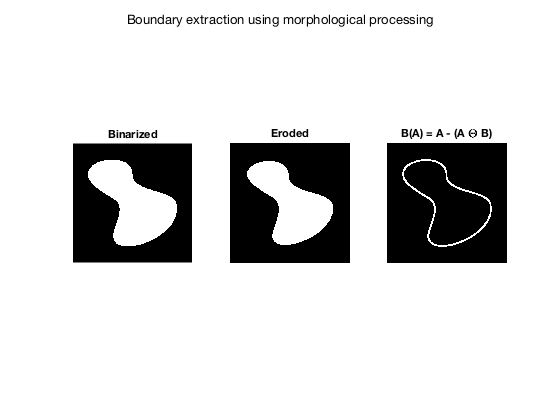

A = imbinarize(I);          % Work on binary image
                            % This is like a threshold segmentation
B = strel('square', 15);        % Structuring element

AeB = imerode(A, B);        % Erosion
BA = A - AeB;               % Subtract eroded image (some edge eroded away) from original

figure; 
subplot(131)
imshow(A);
title('Binarized');
subplot(132)
imshow(AeB);
title('Eroded');
subplot(133)
imshow(BA);
title('B(A) = A - (A \Theta B)');
sgtitle('Boundary extraction using morphological processing')

This method allows varying the amount of erosion, which can then make a wider boundary.

## Part 2. Segmentation based on thresholding

clc; close all; clear all;

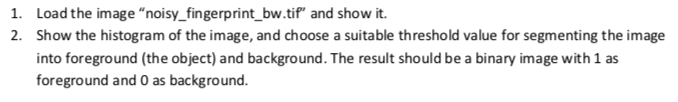

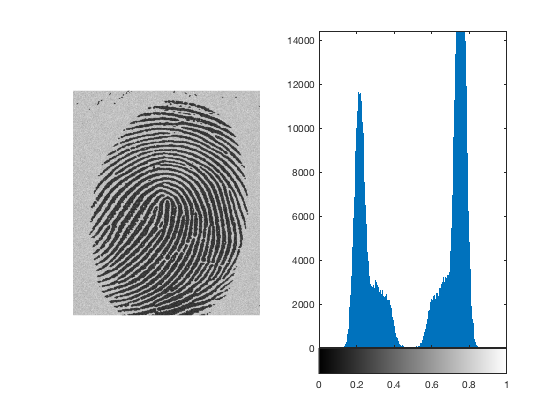

I = im2double(imread('img/noisy_fingerprint_bw.tif')); % read in as double values
figure; 
subplot(121)
imshow(I);
subplot(122)
imhist(I);

The image is a noisy fingerprint.

The histogram shows a bimodal distribution.

To biarize, a manual choice for the threshold will be a value inbetween the two modes.

We want to retain the foreground (the black part) as the 1s in the binary image, so thresholding has to be the logical operation$I<T$.

T = 0.5                     % Manual choice of threshold halfway inbetween modes

T = 0.5000

T_otsu = graythresh(I)      % Using Otsu 1979

T_otsu = 0.4902

The automatic choice of global threshold yields a value close to the manual.

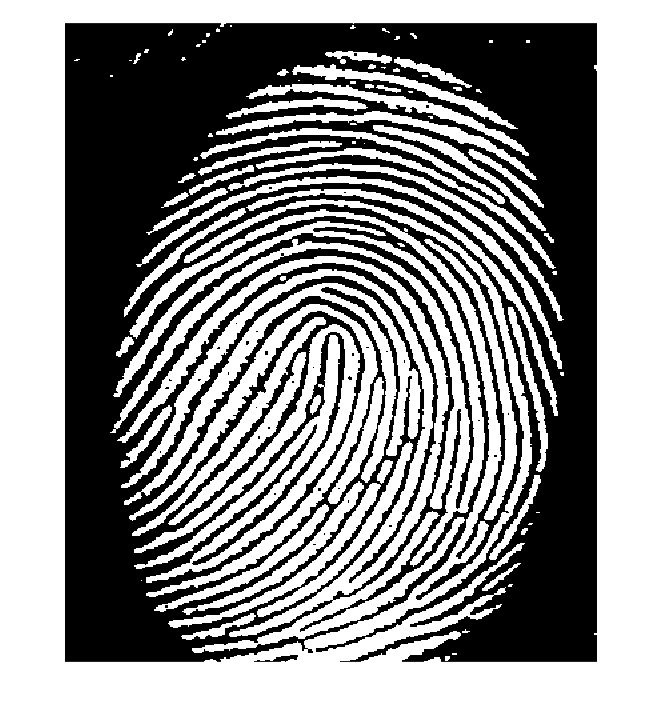

figure; imshow(I<T);

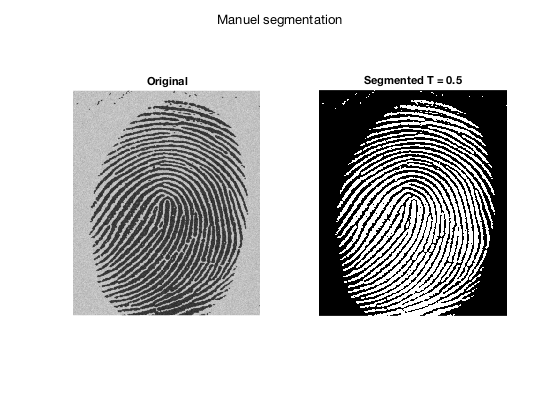

I_seg = I < T;              % Segmentation to separate fingerprint from bg, as binary image
figure; 
subplot(121)
imshow(I);
title('Original')
subplot(122)
imshow(I_seg);
title(['Segmented T = ', num2str(T)])
sgtitle('Manuel segmentation')

Can be cleaned up a bit using opening and closing

Process

- $A$: Segment original image $I$into binary image using $A\left(x,y\right)=\left\lbrace \begin{array}{ll}
1 & I\left(x,y\right)<T\\
0 & \mathrm{otherwise}
\end{array}\right.$

- $I_1$: Remove small grained noise with $A\ominus B$

- $I_2$: Put back useful part eroded away by dilation with B: Total image is $\left(A\ominus B\right)\oplus B=A\circ B$ (opening of A by B)

- $I_3$: Dilate once more by B to make lines clearer: Total image is $\left(A\circ B\right)\oplus B$ 

- $I_4$: Erode by B: $\left(\left(A\circ B\right)\oplus B\right)\ominus B=\left(A\circ B\right)\bullet B$

Recall, 

- $A\circ B=\left(A\ominus B\right)\oplus B$ is the opening of $A$ by $B$.

- $A\bullet B=\left(A\oplus B\right)\ominus B$ is the closing of $A$ by $B$. 

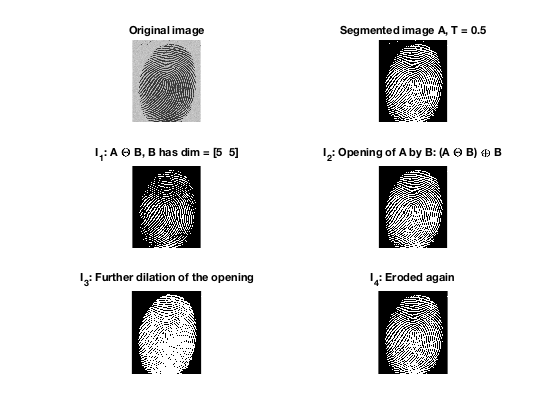

A = I_seg;
B = strel('square', 5);     % structure elem

I1 = imerode(A, B);
I2 = imdilate(I1, B);   % Opening of A by B
I3 = imdilate(I2, B);
I4 = imerode(I3, B);    % Closing of the opening

figure;

subplot(321)
imshow(I);
title('Original image')

subplot(322)
imshow(A);
title(['Segmented image A, T = ', num2str(T)])

subplot(323)
imshow(I1);
title(['I_1: A \Theta B, B has dim = [', num2str(size(B.Neighborhood)), ']'])

subplot(324)
imshow(I2);
title('I_2: Opening of A by B: (A \Theta B) \oplus B')

subplot(325)
imshow(I3);
title('I_3: Further dilation of the opening')

subplot(326)
imshow(I4);
title('I_4: Eroded again')

Image 2, the opening of A by B, appears to give the best basis for recognizing a fingerprint.

## Part 3. Segmentation by morphological watersheds

clc; close all; clear all;

Open blob image

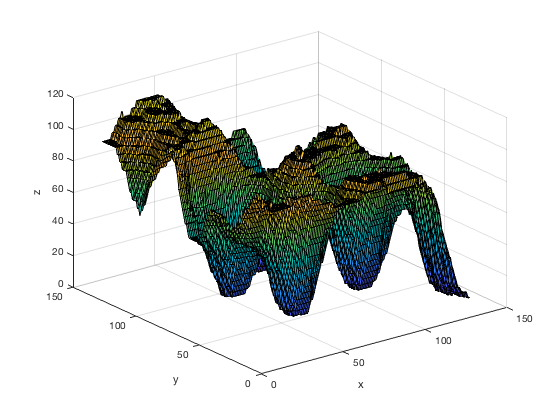

I = imread('img/blob_original.tif');
figure; surf(I);
xlabel('x'); ylabel('y'); zlabel('z'); 

We want to "fill" the contours with water, and draw segmentation boundaries where the water starts "spilling over" into other regions

Perform the watershed with 4-connected regions

conn = 4;
Iout = watershed(I, conn);

See the different regions

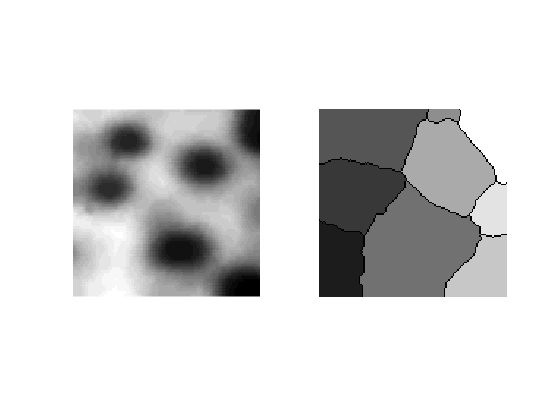

figure; 
subplot(121);
imshow(I, []);      % force using entire grayscale range with []
subplot(122);
imshow(Iout, []);

Extract boundaries only:

regs = im2double((Iout == 0));

Then fuse the two images to have an overlay of the region boundaries ("dams")

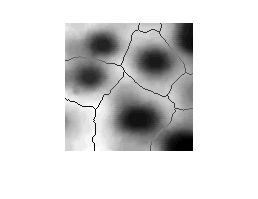

segm = imfuse(im2double(I), regs, 'diff');
figure; imshow(segm); 

The image shows how 9 different regions can be picked out, corresponding to nine different topographical areas on a map.